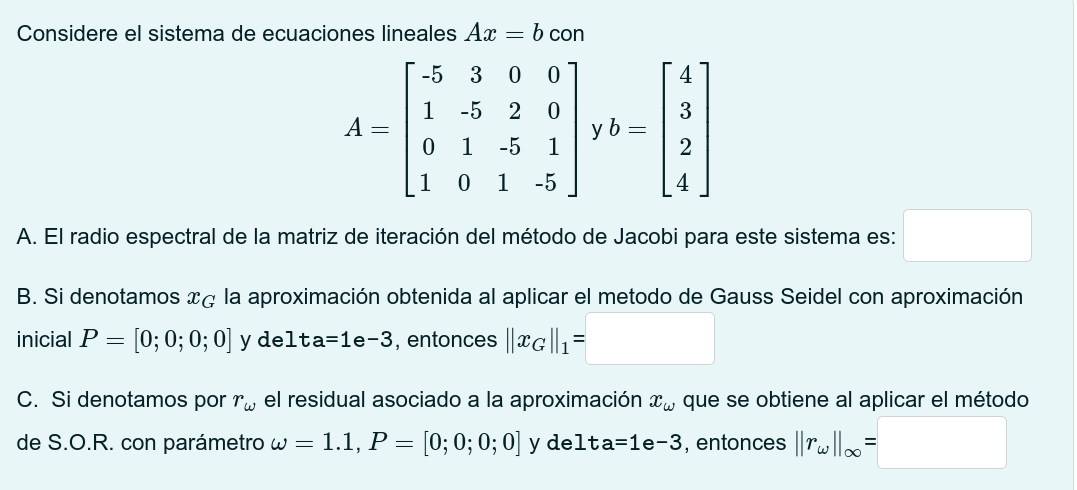

clear
A = [-5 3 0 0;1 -5 2 0;0 1 -5 1;1 0 1 -5]

A =     -5     3     0     0
     1    -5     2     0
     0     1    -5     1
     1     0     1    -5



b = [4 3 2 4]

b =      4     3     2     4



I = diag(diag(A))

I =     -5     0     0     0
     0    -5     0     0
     0     0    -5     0
     0     0     0    -5


U = triu(A) - I

U =      0     3     0     0
     0     0     2     0
     0     0     0     1
     0     0     0     0


L = tril(A) - I

L =      0     0     0     0
     1     0     0     0
     0     1     0     0
     1     0     1     0



J = -inv(I)*(U+L)

J =          0    0.6000         0         0
    0.2000         0    0.4000         0
         0    0.2000         0    0.2000
    0.2000         0    0.2000         0



Rj = max(abs(eig(J)))    

Rj = 0.5085



X = gseid (A, b, [0;0;0;0], 1e-3, 100)

k = 8

X =    -1.5674
   -1.2795
   -0.9152
   -1.2965


norm(X,1)

ans = 5.0586



Y = sor (A, b, zeros(4,1), 1.1, 1e-3, 100)

k = 6

Y =    -1.5672
   -1.2797
   -0.9151
   -1.2965



sor = A*Y

sor =     3.9969
    3.0011
    1.9995
    4.0002



norm(transpose(b) - sor,inf)

ans = 0.0031

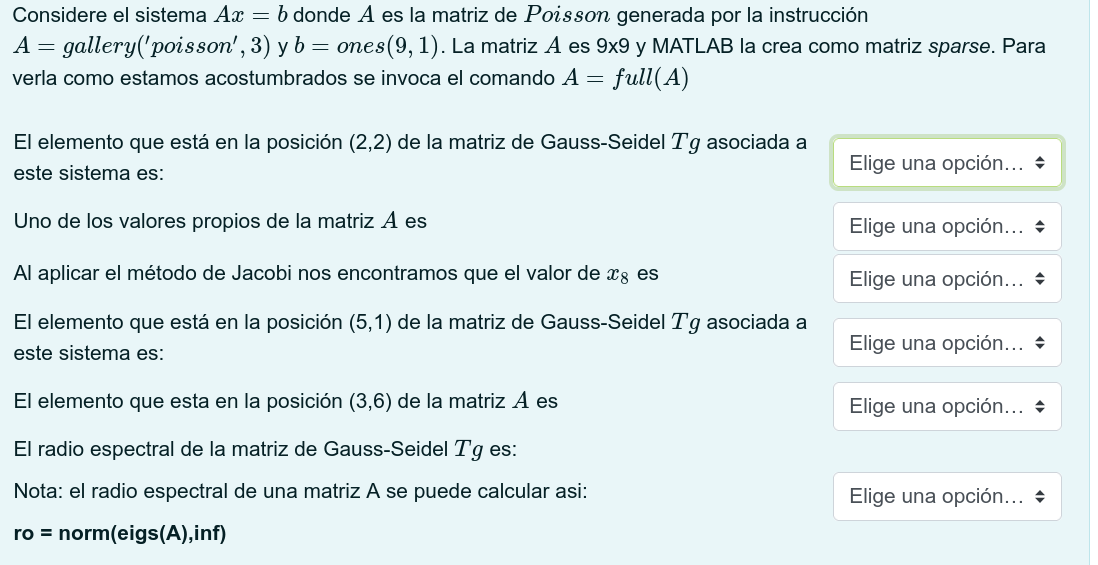

clear
A = gallery("poisson",3)

A = 9×9 sparse double matrix (33 nonzeros)
   (1,1)        4
   (2,1)       -1
   (4,1)       -1
   (1,2)       -1
   (2,2)        4
   (3,2)       -1
   (5,2)       -1
   (2,3)       -1
   (3,3)        4
   (6,3)       -1
   (1,4)       -1
   (4,4)        4
   (5,4)       -1
   (7,4)       -1
   (2,5)       -1
   (4,5)       -1
   (5,5)        4
   (6,5)       -1
   (8,5)       -1
   (3,6)       -1
   (5,6)       -1
   (6,6)        4
   (9,6)       -1
   (4,7)       -1
   (7,7)        4
   (8,7)       -1
   (5,8)       -1
   (7,8)       -1
   (8,8)        4
   (9,8)       -1
   (6,9)       -1
   (8,9)       -1
   (9,9)        4


b = ones(9,1)

b =      1
     1
     1
     1
     1
     1
     1
     1
     1


A = full(A)

A =      4    -1     0    -1     0     0     0     0     0
    -1     4    -1     0    -1     0     0     0     0
     0    -1     4     0     0    -1     0     0     0
    -1     0     0     4    -1     0    -1     0     0
     0    -1     0    -1     4    -1     0    -1     0
     0     0    -1     0    -1     4     0     0    -1
     0     0     0    -1     0     0     4    -1     0
     0     0     0     0    -1     0    -1     4    -1
     0     0     0     0     0    -1     0    -1     4


I = diag(diag(A))

I =      4     0     0     0     0     0     0     0     0
     0     4     0     0     0     0     0     0     0
     0     0     4     0     0     0     0     0     0
     0     0     0     4     0     0     0     0     0
     0     0     0     0     4     0     0     0     0
     0     0     0     0     0     4     0     0     0
     0     0     0     0     0     0     4     0     0
     0     0     0     0     0     0     0     4     0
     0     0     0     0     0     0     0     0     4


U = triu(A) - I

U =      0    -1     0    -1     0     0     0     0     0
     0     0    -1     0    -1     0     0     0     0
     0     0     0     0     0    -1     0     0     0
     0     0     0     0    -1     0    -1     0     0
     0     0     0     0     0    -1     0    -1     0
     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0


L = tril(A) - I

L =      0     0     0     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0     0
     0    -1     0    -1     0     0     0     0     0
     0     0    -1     0    -1     0     0     0     0
     0     0     0    -1     0     0     0     0     0
     0     0     0     0    -1     0    -1     0     0
     0     0     0     0     0    -1     0    -1     0


eig(A)

ans =     1.1716
    2.5858
    2.5858
    4.0000
    4.0000
    4.0000
    5.4142
    5.4142
    6.8284


Gs = -inv(I+L) * U

Gs =          0    0.2500         0    0.2500         0         0         0         0         0
         0    0.0625    0.2500    0.0625    0.2500         0         0         0         0
         0    0.0156    0.0625    0.0156    0.0625    0.2500         0         0         0
         0    0.0625         0    0.0625    0.2500         0    0.2500         0         0
         0    0.0312    0.0625    0.0312    0.1250    0.2500    0.0625    0.2500         0
         0    0.0117    0.0312    0.0117    0.0469    0.1250    0.0156    0.0625    0.2500
         0    0.0156         0    0.0156    0.0625         0    0.0625    0.2500         0
         0    0.0117    0.0156    0.0117    0.0469    0.0625    0.0312    0.1250    0.2500
         0    0.0059    0.0117    0.0059    0.0234    0.0469    0.0117    0.0469    0.1250



norm(eigs(Gs),inf)

ans = 0.5000

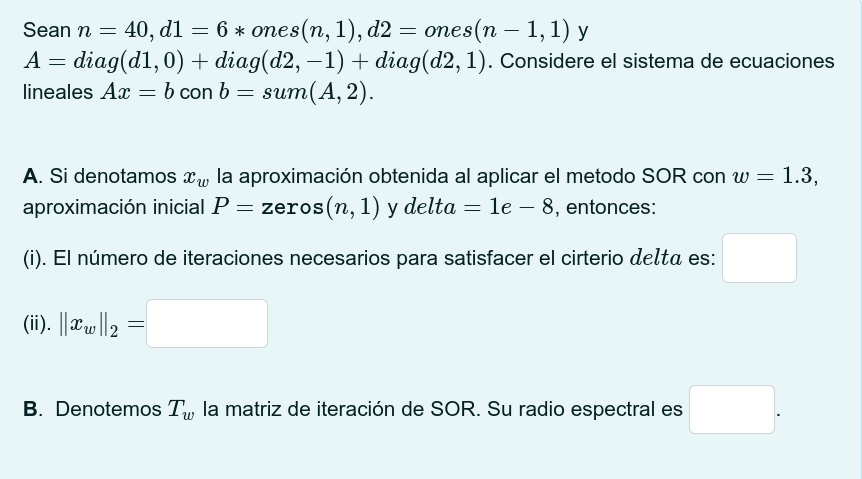

clear
n = 40

n = 40

d1 = 6*ones(n,1)

d1 =      6
     6
     6
     6
     6
     6
     6
     6
     6
     6


d2 = ones(n-1,1)

d2 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



A = diag(d1,0) + diag(d2,-1)+diag(d2,1)

A =      6     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     6     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     6     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     6     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     6  

b = sum(A,2)

b =      7
     8
     8
     8
     8
     8
     8
     8
     8
     8


I = diag(diag(A))

I =      6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     6  

U = triu(A) - I

U =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0  

L = tril(A) - I

L =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0  


Y = sor (A, b, zeros(n,1), 1.3, 1e-8, 100)

k = 23

Y =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



norm(Y,2)

ans = 6.3246


%(D+ωL)−1[(1−ω)D−ωU]

w = 1.3

w = 1.3000


sor = inv(I+ w*L)*((1-w)*I-(w*U))

sor =    -0.3000   -0.2167         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0650   -0.2531   -0.2167         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0141    0.0548   -0.2531   -0.2167         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  




R = max(abs(eig(sor)))

R = 0.3000

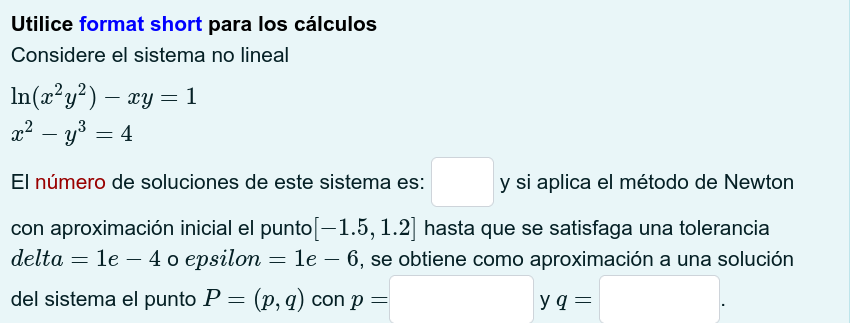

syms f(x,y)
syms g(x,y)

f(x,y) = log(x^2*y^2) - x*y - 1

$$f(x, y) = \log\left(x^{2}\,y^{2}\right)-x\,y-1$$

g(x,y) = x^2 - y^3 - 4

$$g(x, y) = x^{2}-y^{3}-4$$


F = [f, g]

$$F(x, y) = \left(\begin{array}{cc} \log\left(x^{2}\,y^{2}\right)-x\,y-1 & x^{2}-y^{3}-4 \end{array}\right)$$


Jf = jacobian(F)

$$Jf(x, y) = \left(\begin{array}{cc} \frac{2}{x}-y & \frac{2}{y}-x\\ 2\,x & -3\,y^{2} \end{array}\right)$$


F = @(x)[log(x(1)^2*x(2)^2) - x(1)*x(2) - 1, x(1)^2 - x(2)^3 - 4]

F = function_handle with value:
    @(x)[log(x(1)^2*x(2)^2)-x(1)*x(2)-1,x(1)^2-x(2)^3-4]



jf = @(x) [2/x(1) - x(2), 2/x(2) - x(1); 2*x(1),-3*x(2)^2]

jf = function_handle with value:
    @(x)[2/x(1)-x(2),2/x(2)-x(1);2*x(1),-3*x(2)^2]



[P, iter, err] = newdim (F, jf, [-1.5,1.2], 1e-4, 1e-6, 100)

P =    -2.0297    0.4927


iter = 5

err = 3.2558e-07